## **Question:**

A Stewart platform is a flat surface connected to a base via six linear actuators; the position and orientation of the surface can be fully controlled within bounds. A common application is to capture a ball thrown at the platform by orienting the surface such that the ball bounces toward the center. Devices typically include cameras that determine the incoming ball’s position and velocity. This leaves the question which we examine in this essay: given the trajectory of a ball travelling towards a planar surface, what is the angle of the plane required to direct the ball’s bounce trajectory toward a desired point?

## **Method:**

### Method1

We present two independent methods for modeling the ball’s trajectory before and after bouncing on the surface. The first is an explicit solution using the parametric equations of motion of a falling body. The position of the ball is denoted as $P(t) = \left(
\matrix{
x(t) \cr
y(t) \cr
z(t)
}
\right)}$, with initial velocity 

#### Ball Kinematics

$V_i = \left(
\matrix{
V_{ix} \cr
V_{iy} \cr
V_{iz}
}
\right)}$, and acceleration $A(t) = \left(
\matrix{
0 \cr
0 \cr
-9.80
}
\right)}$. The vector equation for constant linear acceleration is

$P(t) = P(0) + V_i t + \frac{1}{2} A t^2$ . (1)

The bounce occurs where the position vector coincides with the plane, i.e. $\vec{P(t_b)} \cdot \vec{N} = 0$ for some value $t_b$, where $\vec{N}$ is the normal vector of the plane (we assume it passes through the origin). This can be expanded to

$\vec{P(t_b)} \cdot \vec{N} = \frac{1}{2} (\vec{A} \cdot \vec{N}) t_b^2 + (\vec{V_i} \cdot \vec{N}) t_b + \vec{P(0)} \cdot \vec{N} = 0$, (2)

and applying the quadratic formula gives

$t_b = \frac{-\vec{V_i} \cdot \vec{N} \pm \sqrt{(\vec{V_i} \cdot \vec{N})^2 - 2 (\vec{P(0)} \cdot \vec{N}) (\vec{A} \cdot \vec{N})}}{\vec{A} \cdot \vec{N}}$ . (3)

Thus we can then substitute this back into the original kinematics equation (1) to get the bounce position function:

$P(t_b) = P(0) + V_i t_b + \frac{1}{2} A t_b^2$ (4)

Since two values of $t_b$ result, the greater of the two is chosen, so that the ball makes a high arcing trajectory and impacts with the top of the plane. Then the position of the bounce at time $t_b$ is given by equation (4). 

#### Ball Impact

At the point of impact, the ball has velocity $V_f = V_i + At$. The component of the final velocity perpendicular to the plane (parallel with the normal vector) is

$\vec{V_{\bot}} = \frac{\vec{V_f} \cdot \vec{N}}{\|\vec{N}\|^2} \vec{N}$. (5)

Then the rebound velocity has the opposite perpendicular component, scaled by the coefficient of restitution (COR):

$\vec{V_{rebound}} = \vec{V_f} - (1 + COR) \vec{V_{\bot}} = \vec{V_f} - (1 + COR) \frac{\vec{V_f} \cdot \vec{N}}{\|\vec{N}\|^2} \vec{N}$. (6)

At this point the formulas may be applied again, with $P(0) = P(t_b)$ and $V_i = V_{rebound}$, to determine the position of the next bounce; subsequent bounces are defined recursively.

### **Method 2**

We also implement a hybrid numeric solution by integrating over the acceleration with the ordinary differential equation solver, ode45. At each time step, the position increments proportionally to the velocity, and the velocity in the z direction changes with the acceleration. The simulation is stopped by an event function at the point of the bounce, as above, when the dot product of the position vector and the normal vector is equal to zero. Then it is reset with the new velocity after the bounce, according to equation (5) above. This method has the advantage of generating points along the trajectory, which are plotted in Figure 1.

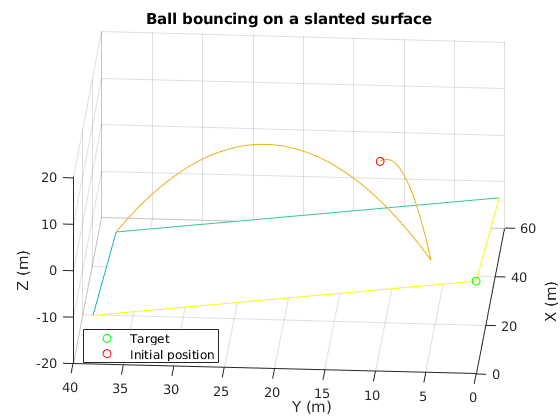

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 20];
v_0 = [2; -2; 2];
normal = [0.15; 0.25; 1]; % this value may be overwritten later
origin = [0; 0; 0];

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(normal), [0, 0], true);
figure()
plot_bounce(States, p_0, normal', T, endTimes);
view([274.1 38.1])
title('Ball bouncing on a slanted surface');

## Results

    Now that we have the explicit function for the position of the ball's future bounces, given a set of its initial conditions and surface orientation, we can then use established numerical optimization methods to control the ball's bounces such that it lands at a desired target position, if possible. This idea behind the controller is that once we have a function that gives us end position as a function of surface orientation (normal vector), we can then use optimizers such as `fminsearch` to optimize a cost function, which in this case is the distance from the target. We can then test this controller against our previously developed numerical simulation by calculating the ideal surface orientation while the simulation is running, as if the controller were running in real time on a physical system.

    To demonstrate this controller, we can first test for cases where the table only needs to be adjusted once, such that the trajectory exiting the first bounce will end with the ball at the target position. We choose these cases first because they are the easiest to represent in a single static image, as one does not need to consider displaying the movement of the surface, and the associated changes in the bounce Z positions.

    Using the initial position $\vec{P(0)} = \left[
\matrix{
10 \cr
10 \cr
15
}
\right]$and initial velocity $\vec{V(0)} = \left[
\matrix{
2 \cr
-2 \cr
2
}
\right]$, we arrive at the following simulation resuls:

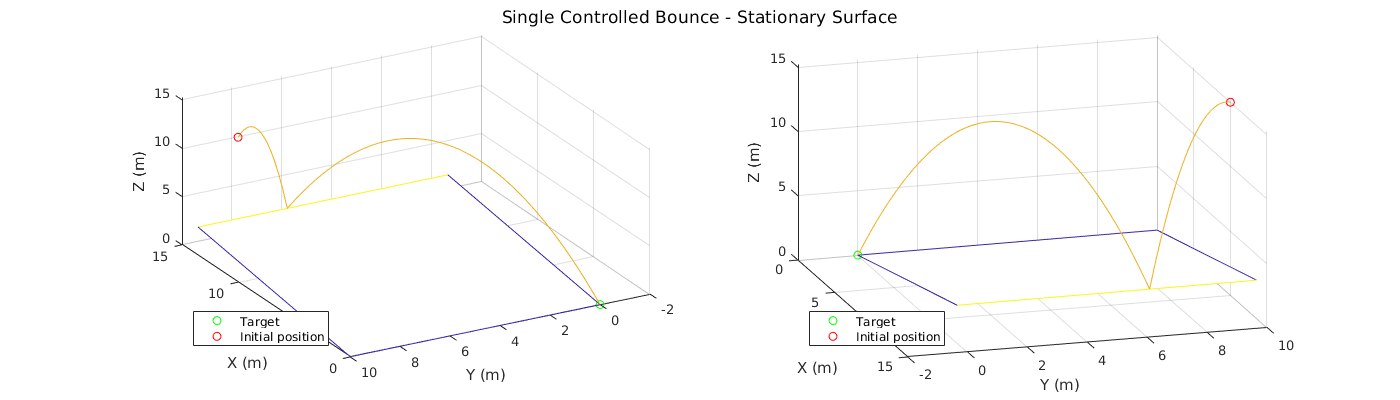

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 15];
v_0 = [2; -2; 2];
origin = [0; 0; 0];

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], false);

figure();
set(gcf, 'position', [0 0 1400 400])
sgtitle("Single Controlled Bounce - Stationary Surface")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(240.7, 41.2)
legend('Target', 'Initial position', 'Location',"southwest")

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(73, 27.4)
legend('Target', 'Initial position', 'Location',"southwest")

    As expected, the calculated optimal surface orientation correctly aim's the ball's second bounce to the target position (the origin, $(0, 0, 0)$), only using a single bounce to do so. We can also control such that the ball's $n$th bounce arrives at the target position, not jus the second bounce. 

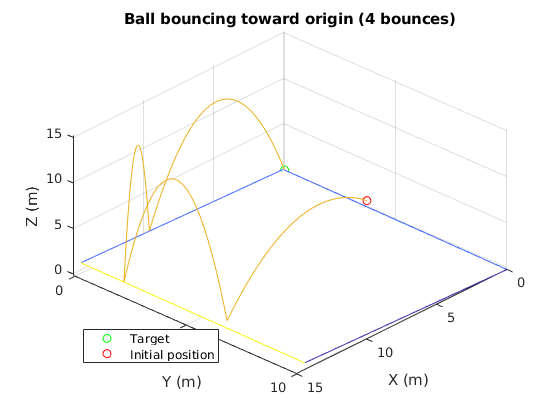

stationary_target = [0, 0];
nBounces = 4;

func_Posf_of_N = @ (N) landing_position(N, nBounces, g, coeff_restitution, v_0, p_0);
func_XofN = @ (N) (dot(func_Posf_of_N(N), [1 0 0]));
func_YofN = @ (N) (dot(func_Posf_of_N(N), [0 1 0]));

func_DistofN = @ (N) ((func_XofN(N) - stationary_target(1))^2 + (func_YofN(N) - stationary_target(2))^2);

search_options = optimset('MaxFunEvals', 1000);
N = fminsearch(func_DistofN, [0; 0; 1], search_options);
N = N/norm(N);

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(N), stationary_target, true);
figure()

plot_bounce(States, p_0, N', T, endTimes);
view([133.2 45.6]);
title('Ball bouncing toward origin (4 bounces)');

    This raises the question: Even if the controller can get the ball to the center, can it *keep* the ball at the center? Since the ball is approaching with a certain amount of X and Y velocity, can we truly negate this, preventing the ball from just bouncing past the center? To test this we set up a scenario where given the set of initial conditions the first bounce of the ball would land directly at the target position. Thus, we can see if the controller-generated surface orientations are able to negate the horizontal velocity components and keep the ball at the center. 

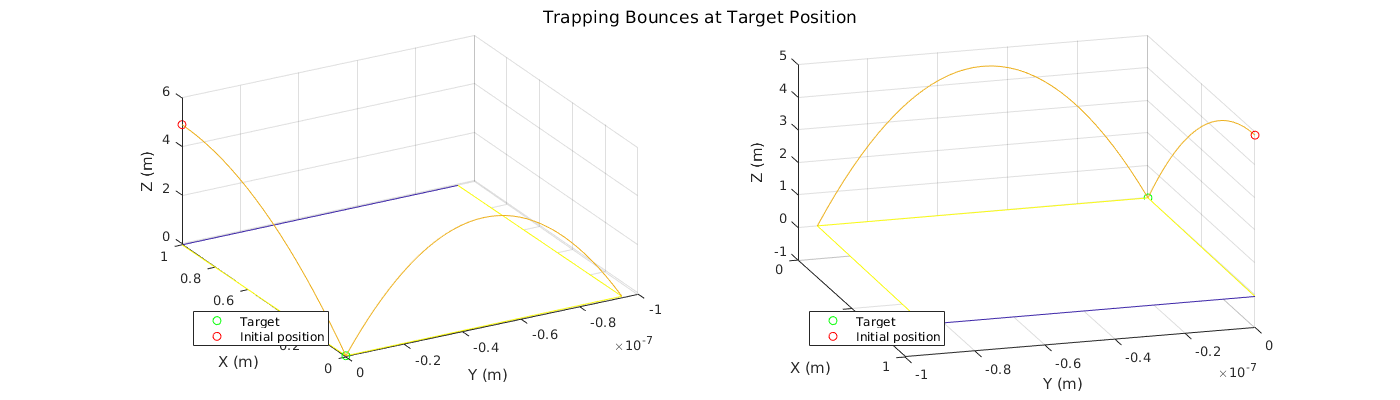

v_0 = [-1; 0; 0];
p_0 = [1; 0; -(1^2 * g) / (2 * v_0(1))];
nBounces = 2;

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], false);

figure();
set(gcf, 'position', [0 0 1400 400])
sgtitle("Trapping Bounces at Target Position")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(240.7, 41.2)
legend('Target', 'Initial position', 'Location',"southwest")

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals(1, :), T, bounceTimes);
view(73, 27.4)
legend('Target', 'Initial position', 'Location',"southwest")

    While at first it may seem as if the controller is unable to keep the ball at the center, the scale of the Y axis ($10^{-7}$) reveals that in fact, the controller is actually able to keep the ball in the center. Thus, we have established that 1) The controller is able to direct balls to land at the center, if possible, and 2) Once a ball lands at the center, the controller is able to keep it there.

    This leaves us with one last problem. So far, all simulations of the bouncing ball system have been with a single bounce. However, to truly simulate the system realistically, and to account for cases where the ball physically cannot bounce to the center with just one bounce, a simulation that allows for control of multiple consecutive bounces is required. We can test such a simulation with a scenario where the ball is unable to bounce to the center in one try. Such a scenario can be set up if, using the same $\vec{V(0)} = \left[
\matrix{
2 \cr
-2 \cr
2
}
\right]$ as in the first example, we instead move the starting position to$\vec{P(0)} = \left[
\matrix{
50 \cr
50 \cr
20
}
\right]$. In this case, for the ball to bounce to the target location, additional bounces, and therefore surface adjustments, will be needed. Unfortunately, there is not good way to plot the surface orientation adjustments in a stationary plot. To approximate this, we instead can plot the surface orientation at the time of each bounce at each bounce location.

p_0 = [50; 50; 20];
nBounces = 15;

[T, States, Normals, ~, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, [0, 0], true);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 3298.719145 



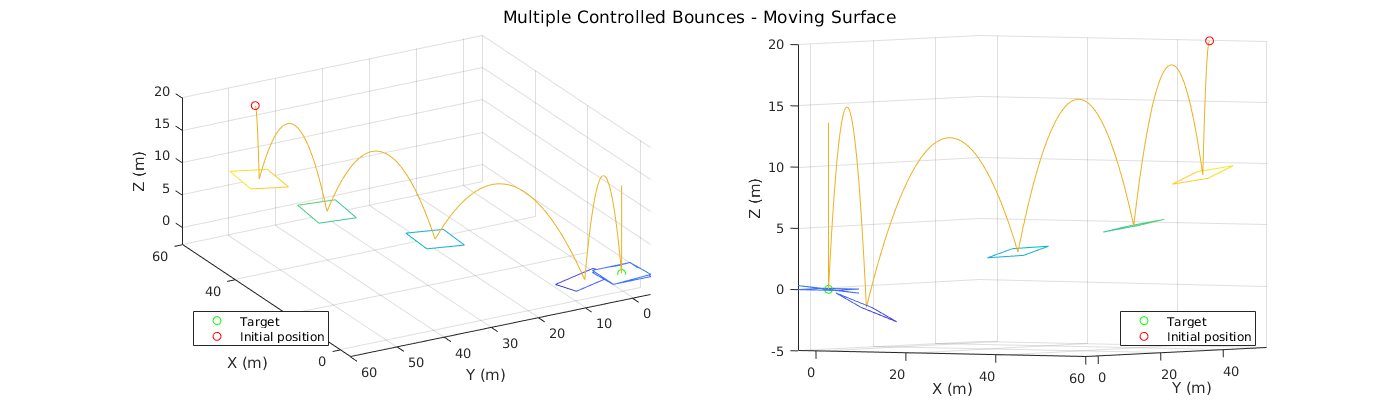

figure()
set(gcf, 'position', [0 0 1400 400])
sgtitle("Multiple Controlled Bounces - Moving Surface")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view(240.7, 41.2)

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view(32.2179, 2.1489)
ax = gca;
ax.Legend.Location = 'southeast';

Notice that there are 6 distinct planes that are visible in these plots. However, this simulation was set up such that the ball will bounce 15 times. The remaining 9 planes are missing because they are all overlapping each other at the target position, as since the ball has arrived at the target position and has had its horizontal velocity components negated, forming the vertical trajectory at the target position. This becomes even clearer when one plots the distance to the target over time:

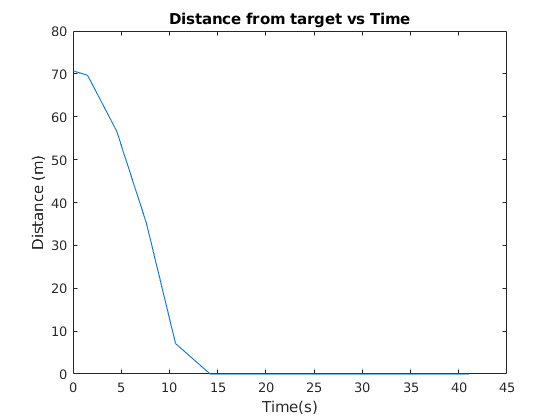

figure()
distances = sqrt(States(:, 1).^2 + States(:, 2).^2);
plot(T, distances);
title("Distance from target vs Time")
xlabel('Time(s)')
ylabel("Distance (m)")

This confirms that the ball is able to be kept at the target position by the controlled surface

Now that we can optimize the surface orientation such that the ball can be controlled towards an arbitrary target position, it is a very straightforward extension to allow for the ball to be controlled to moving target positions. Here, we simulate for a set of targets that are moving along the line $y = x$

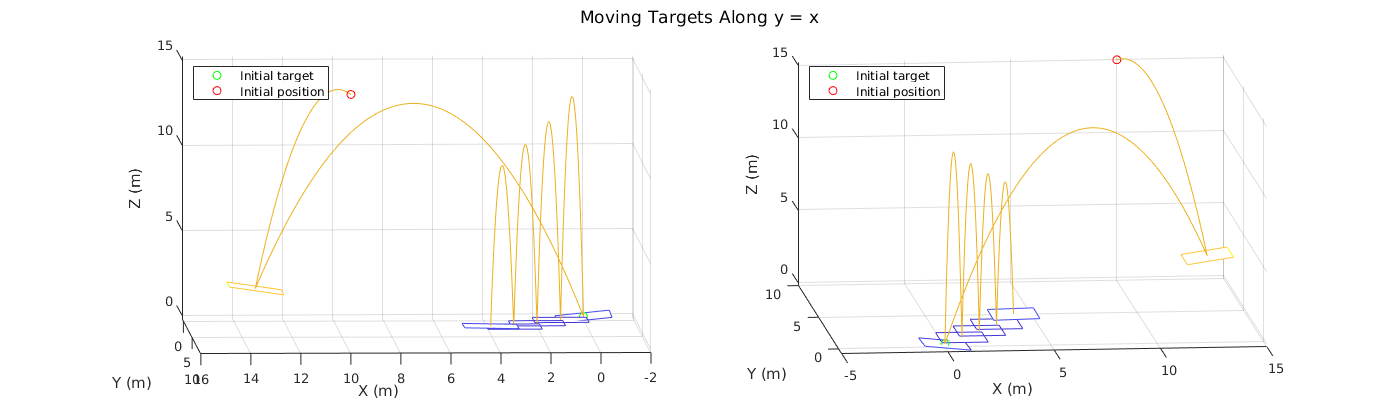

p_0 = [10; 10; 15];
v_0 = [2; -2; 2];

Targets = [0, 0;
            0, 0;
            1, 1;
            2, 2;
            3, 3;
            4, 4;];
target = [0, 0];

nBounces = size(Targets, 1);

[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, Targets, true);

figure()
set(gcf, 'position', [0 0 1400 400])
sgtitle("Moving Targets Along y = x")

subplot(1, 2, 1)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view([177.6 7.6])
ax = gca;
ax.Legend.Location = 'northwest';
ax.Legend.String{1} = 'Initial target';

subplot(1, 2, 2)
plot_bounce(States, p_0, Normals, T, bounceTimes);
view([-5.9 17.1])
ax = gca;
ax.Legend.Location = 'northwest';
ax.Legend.String{1} = 'Initial target';

The animations for both the stationary and moving targets can be found in the current Matlab directory, as well as in [this Google Drive folder](https://drive.google.com/file/d/1E7PqvRqAxDsxt5zaqsuFkQQZe01mHJP_/view?usp=sharing)

## Interpretation

Our model correctly predicts the orientation of the platform’s surface which causes the ball to bounce towards an arbitrary point. Under ideal conditions, we show that it is possible to perfectly target a point, and that no difference is apparent between analytic and numeric methods. The target point can be reached with as long as the initial position is sufficiently close to the target, or the initial velocity is sufficiently great; even if the ball is oriented directly at the target, it can be made to bounce vertically and land in the same place again. Further work is needed to quantify maximum distance and minimum velocity necessary to reach the target; one approach would be to solve for the normal vector analytically instead of using fminsearch.

Further iterations of this model should also include the effects of air resistance, the ball’s spin, and proper collision physics. In our model, we assume an instantaneous collision in which the ball’s rebound velocity is scaled by the coefficient of restitution; in reality, the compression of the ball and friction of the surface impact the system’s behavior in complex ways.

Perhaps a more important observation is that the velocity of the surface may be manipulated to either “cradle” the ball, by assuming the same velocity at the time of impact and slowly decelerating to capture the ball, or to “punch” the ball by having an upward velocity, thereby increasing the range of its trajectory. Our model is limited to angular control with the plane passing through the origin, when in fact, the Stewart platform has linear as well as angular degrees of freedom. This may increase the range of scenarios in which the target can be reached and make the device perform better under non-ideal conditions.

Finally, once the optimal orientation for the surface is determined using the methods above, this result must be translated into linear actuations of the Stewart platform’s pistons. This is not a straightforward operation, but it is well documented in other forums.